% Read the WAV file
[audio, fs] = audioread('secretmsg.wav');
disp(fs); % fs = 22050 Hz

       22050



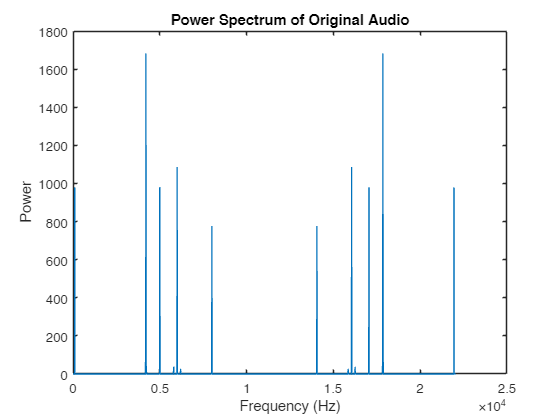


% Compute the FFT (Fast Fourier Transform) of the original audio signal.
N = length(audio);
f = (0:N-1)*(fs/N); % Frequency vector
audio_fft = fft(audio);
power_audio = abs(audio_fft).^2/N; % Power spectrum

% Plot the power spectrum of the original audio signal for analysis
figure;
plot(f, power_audio);
title('Power Spectrum of Original Audio');
xlabel('Frequency (Hz)');
ylabel('Power');

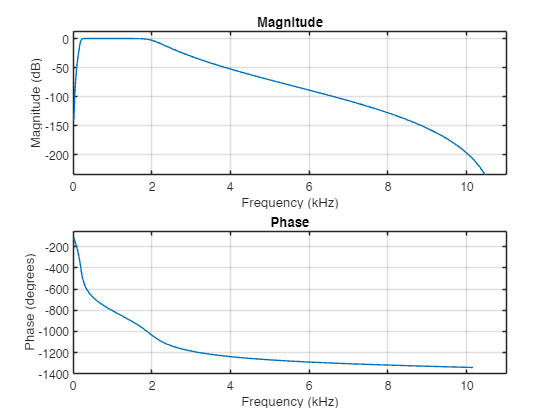


% Design a bandpass filter
[b, a] = butter(7, [200, 2000]/(fs/2), 'bandpass'); % 7th-order bandpass Butterworth filter. b and a are the numerator and denominator coefficients of the filter's transfer function.
% Plot the magnitude and phase responses of the filter for analysis
freqz(b,a,[],fs);

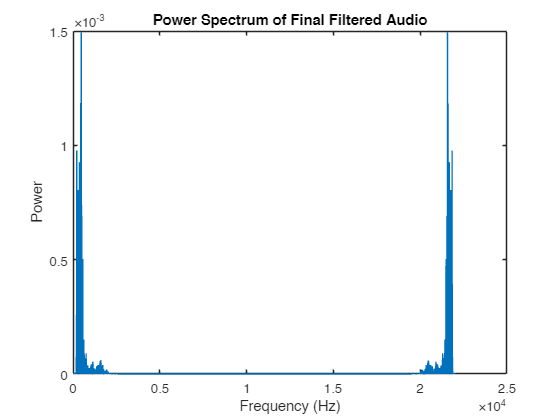


% Input the original audio signal to the bandpass filter
filtered_audio = filtfilt(b, a, audio);
% Compute the FFT of the filtered audio signal
filtered_audio_fft = fft(filtered_audio);
power_filtered_audio = abs(filtered_audio_fft).^2/N; % Power spectrum of the filtered audio signal
% Plot the power spectrum of the filtered audio signal
figure;
plot(f, power_filtered_audio);
title('Power Spectrum of Final Filtered Audio');
xlabel('Frequency (Hz)');
ylabel('Power');


% Play the original and filtered audio signal
sound(audio, fs); % Play original audio signal
pause(length(audio)/fs + 1); % Wait for the audio to finish
sound(filtered_audio*50, fs); % Play filtered audio signal

% Save the filtered audio (optional)
% audiowrite('filtered_audio_file.wav', filtered_audio, fs);